# **Tutorial 1: MATLAB basics**

### Section 1: Expressions

One can use MATLAB as a plain calculator:

(5+13)/3

ans =           6.00


Addition, subtraction, multiplication, division, exponentiation operators:

%Commenting inside the code
%Examples:

4+5 %here I compute 4 plus 5

ans =           9.00


7-2

ans =           5.00


7*9

ans =          63.00


3/4

ans =           0.75


4\3

ans =           0.75


2^7

ans =         128.00


You can set the format to be short or long (decimal point):

format long

2/3

ans =    0.666666666666667



format short 

2/3

ans = 0.6667


format compact

5/7

ans = 0.7143


format loose

5/7

ans = 0.7143

%Precedence rules:

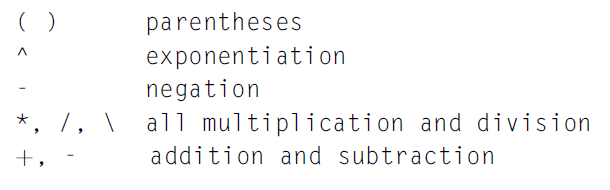

2+2/2

ans = 3


(2+2)/2

ans = 2


5-(6*(4-2))

ans = -7

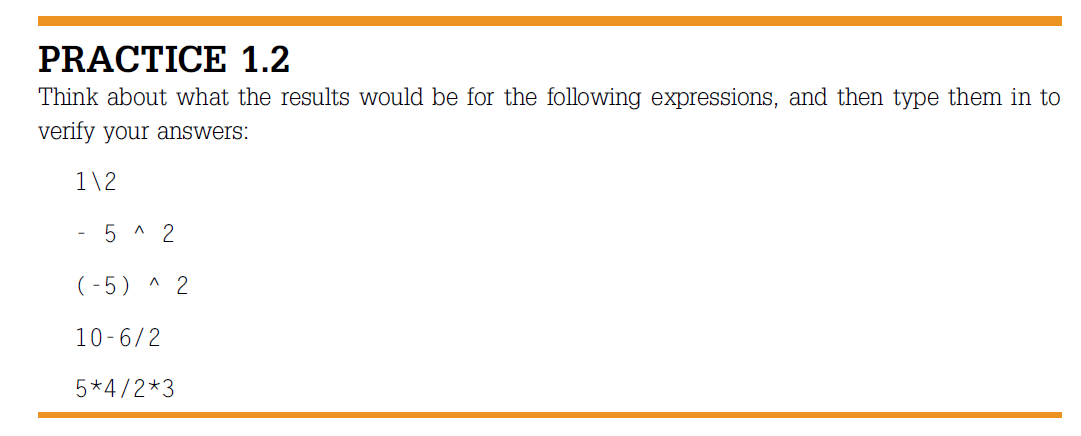

Take two minutes to solve it and report results in chat (use print-screen).

%code here:
1\2  %    1/2

ans = 2


-5^2

ans = -25


(-5)^2

ans = 25


10-6/2

ans = 7


5*4/2*3

ans = 30

### Section 2: Variables and their Types

Assignment is performed via **variable = expression:**

myname = 'Arik'

myname = 'Arik'

myname_str = "Arik"

myname_str = "Arik"

whos

  Name            Size            Bytes  Class     Attributes

  B_1             1x1                 8  double              
  P               1x1                 8  double              
  ans             1x1                 8  double              
  high            1x1                 8  double              
  low             1x1                 8  double              
  months          1x1                 8  double              
  myname          1x4                 8  char                
  myname_str      1x1               150  string              
  n               1x1                 8  double              
  r               1x1                 8  double              
  t               1x1                 8  double              
  t_2             1x1                 8  double              
  val             1x1                 4  int32               
  x               1x1                 8  double              
  y               1x1                 8  double              
  years


strcat(myname,"_", myname_str)

ans = "Arik_Arik"


x = 5

x = 5

x = int8(x)

x = int8
5


whos

  Name            Size            Bytes  Class     Attributes

  B_1             1x1                 8  double              
  P               1x1                 8  double              
  ans             1x1               154  string              
  high            1x1                 8  double              
  low             1x1                 8  double              
  months          1x1                 8  double              
  myname          1x4                 8  char                
  myname_str      1x1               150  string              
  n               1x1                 8  double              
  r               1x1                 8  double              
  t               1x1                 8  double              
  t_2             1x1                 8  double              
  val             1x1                 4  int32               
  x               1x1                 1  int8                
  y               1x1                 8  double              
  years


y = x + 2

y = int8
7


%2 = x is wrong! try it...

z = (2 == x)

z = logical
   0



y = y+1

y = int8
8

%reminder: useful built-in functions:

namelengthmax %gives the maximum length of a variable name

ans = 63


who %what variables we are using


Your variables are:

B_1         P           ans         high        low         months      myname      myname_str  n           r           t           t_2         val         x           y           years       z           




whos %more details on our variable

  Name            Size            Bytes  Class      Attributes

  B_1             1x1                 8  double               
  P               1x1                 8  double               
  ans             1x1                 8  double               
  high            1x1                 8  double               
  low             1x1                 8  double               
  months          1x1                 8  double               
  myname          1x4                 8  char                 
  myname_str      1x1               150  string               
  n               1x1                 8  double               
  r               1x1                 8  double               
  t               1x1                 8  double               
  t_2             1x1                 8  double               
  val             1x1                 4  int32                
  x               1x1                 1  int8                 
  y               1x1                 1  int8         


whos z %specific query about a variable

  Name      Size            Bytes  Class      Attributes

  z         1x1                 1  logical              



Note that variables have types (char, double, integer). Familiar from previous programming courses?

val = 6+3

val = 9


whos

  Name            Size            Bytes  Class      Attributes

  B_1             1x1                 8  double               
  P               1x1                 8  double               
  ans             1x1                 8  double               
  high            1x1                 8  double               
  low             1x1                 8  double               
  months          1x1                 8  double               
  myname          1x4                 8  char                 
  myname_str      1x1               150  string               
  n               1x1                 8  double               
  r               1x1                 8  double               
  t               1x1                 8  double               
  t_2             1x1                 8  double               
  val             1x1                 8  double               
  x               1x1                 1  int8                 
  y               1x1                 1  int8         


val = int32(val)

val = int32
9


whos

  Name            Size            Bytes  Class      Attributes

  B_1             1x1                 8  double               
  P               1x1                 8  double               
  ans             1x1                 8  double               
  high            1x1                 8  double               
  low             1x1                 8  double               
  months          1x1                 8  double               
  myname          1x4                 8  char                 
  myname_str      1x1               150  string               
  n               1x1                 8  double               
  r               1x1                 8  double               
  t               1x1                 8  double               
  t_2             1x1                 8  double               
  val             1x1                 4  int32                
  x               1x1                 1  int8                 
  y               1x1                 1  int8         



intmin("int8")

ans = int8
-128

intmax("int8")

ans = int8
127


z = int8(-200)

z = int8
-128

z = int8(200)

z = int8
127

### Section 3: Built-In Functions, Constants, and Random Numbers

#### Print out all built-in functions:

help elfun

  Elementary math functions.
 
  Trigonometric.
    sin         - Sine.
    sind        - Sine of argument in degrees.
    sinh        - Hyperbolic sine.
    asin        - Inverse sine.
    asind       - Inverse sine, result in degrees.
    asinh       - Inverse hyperbolic sine.
    cos         - Cosine.
    cosd        - Cosine of argument in degrees.
    cosh        - Hyperbolic cosine.
    acos        - Inverse cosine.
    acosd       - Inverse cosine, result in degrees.
    <a href="m

Print out help on specific function:

help abs

 abs    Absolute value.
    abs(X) is the absolute value of the elements of X. When
    X is complex, abs(X) is the complex modulus (magnitude) of
    the elements of X.
 
    See also sign, angle, unwrap, hypot.

    Documentation for abs
    Other uses of abs




abs(-14)

ans = 14


abs(10)

ans = 10

%abs = 5   %if you accidently used a reserved name (of function), 
            % it overrides it and you won't be able to use it

abs(-17)   %Error

ans = 17

%clear abs

abs(-17)

ans = 17

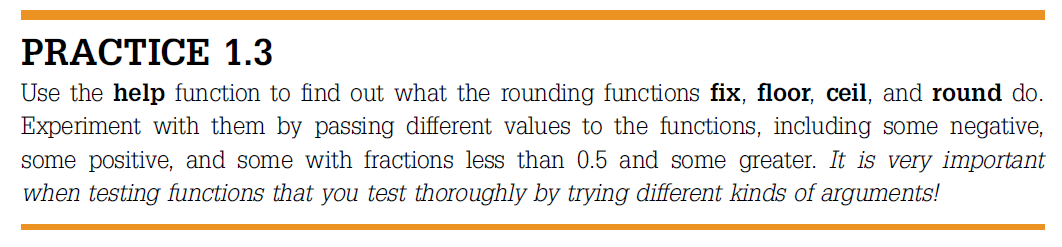

x = exp(1) %the constant e

x = 2.7183


log(x)

ans = 1


log2(x)

ans = 1.4427


y = 16

y = 16

log2(y)

ans = 4




log10(x)

ans = 0.4343

log10(y)

ans = 1.2041


log10(100)

ans = 2

#### Constants in MATLAB:

pi

ans = 3.1416

i

ans = 0.0000 + 1.0000i

j

ans = 0.0000 + 1.0000i

inf

ans = Inf

NaN

ans = NaN

#### Random numbers:

Very useful in Simulations.

help rand

 rand Uniformly distributed pseudorandom numbers.
    R = rand(N) returns an N-by-N matrix containing pseudorandom values drawn
    from the standard uniform distribution on the open interval(0,1).  rand(M,N)
    or rand([M,N]) returns an M-by-N matrix.  rand(M,N,P,...) or
    rand([M,N,P,...]) returns an M-by-N-by-P-by-... array.  rand returns a
    scalar.  rand(SIZE(A)) returns an array the same size as A.
 
    Note: The size inputs M, N, P, ... should be nonnegative integers.
    Negative integers are treated as 0.
 
    R = rand(..., CLASSNAME) returns an array of uniform values of the 
    specified class. CLASSNAME can be 'double' or 'single'.
 
    R = rand(..., 'like', Y) is an array of uniform values with the same
    data type and complexity (real or complex) as the numeric variable Y.
 
    The sequence of


rand   %random numbers between (0,1)

ans = 0.5584


rand

ans = 0.3881

rng(1000) %setting seed

%every time I re-run the code, I get the same sequence

rand 

ans = 0.6536


rand

ans = 0.1150


rand

ans = 0.9503


rand 

ans = 0.4822


rand

ans = 0.8725

rng('shuffle') %shuffling

%every time I re-run the code, I get different sequences

rand 

ans = 0.1943


rand

ans = 0.4767

rng('shuffle')
%Generate random number between 5 and 10:

low= 5

low = 5

high = 10

high = 10


x = low+rand*(high-low)

x = 7.1471

%Generate random integers:
randi([1,2])

ans = 1

randi([1,2])

ans = 1

randi([1,2])

ans = 2

randi([1,2])

ans = 2

randi([1,2])

ans = 2

randi([1,2])

ans = 2


randi([1,10])

ans = 1


randi([-10,10])

ans = 10


randi([1,100])

ans = 71

### Section 4: Relational Expressions

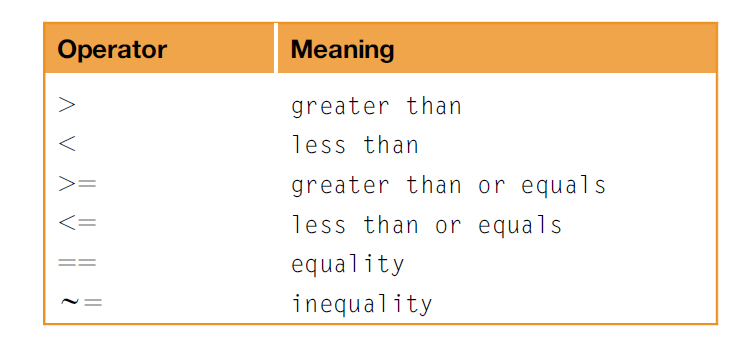

5>6

ans = logical
   0



9>2

ans = logical
   1



'a'>'b'

ans = logical
   0



'b'>'a'

ans = logical
   1


Logical operators:

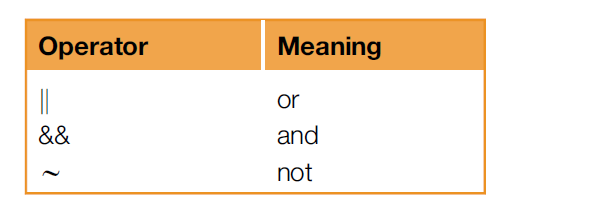

5>3 && 2>3  %Guess: 

ans = logical
   0



10>9 && 'a'=='a' %Guess: 

ans = logical
   1



7>8 || 4>-1   %Guess: 

ans = logical
   1



~(10>9)   %Guess: False/True?

ans = logical
   0


Truth table:

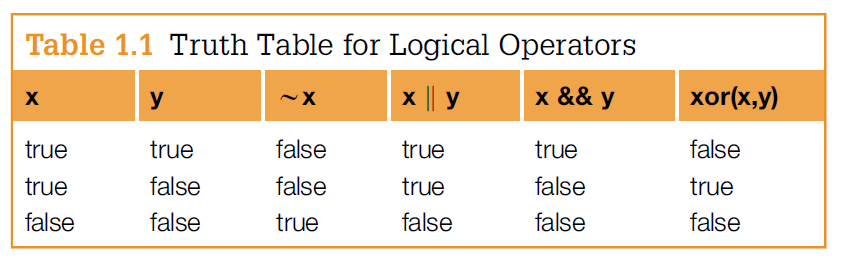


xor('a'=='a', 5>2)   %Guess: 

ans = logical
   0



xor('a'=='a', 2<2)  % Guess: 

ans = logical
   1


**Complete precedence rules:**

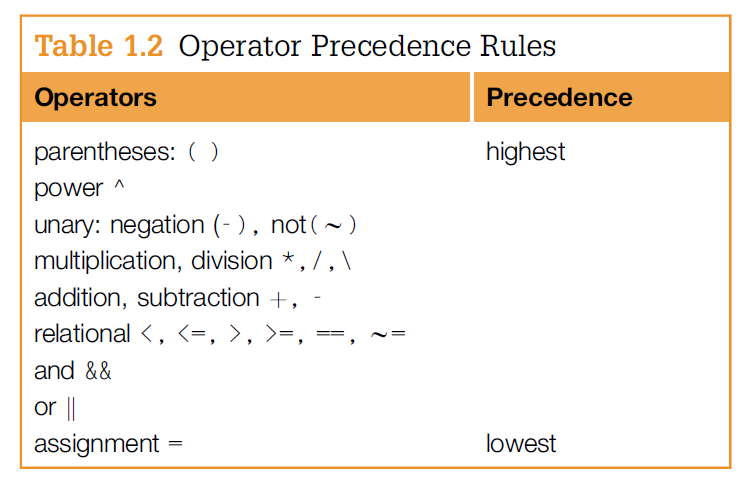

**Let's play a guessing game :)**

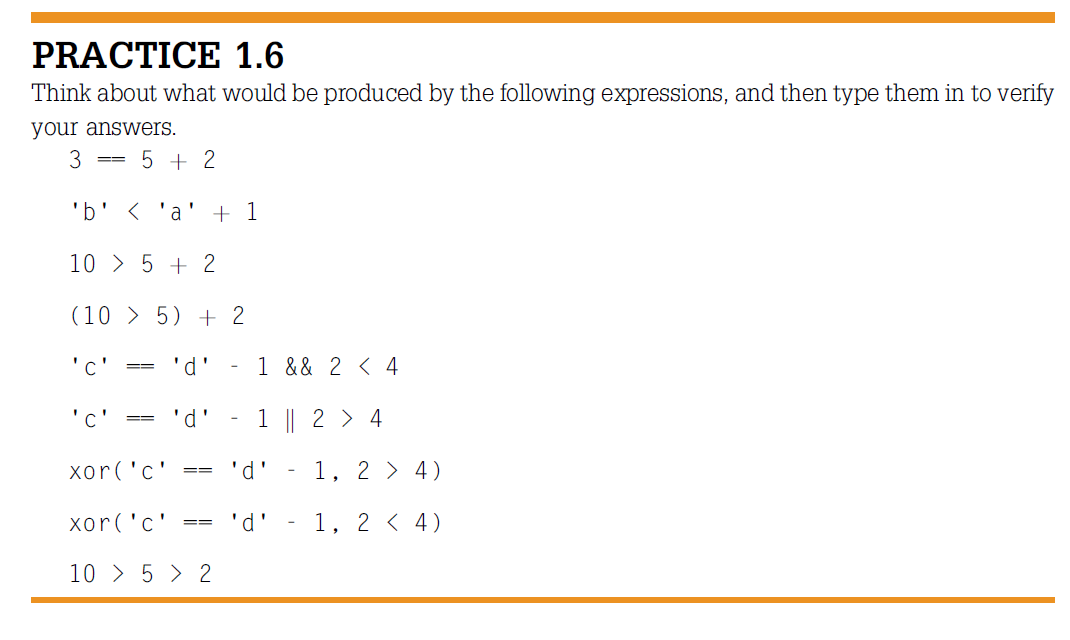

# Now, let's switch to scripts.

and solve the following:

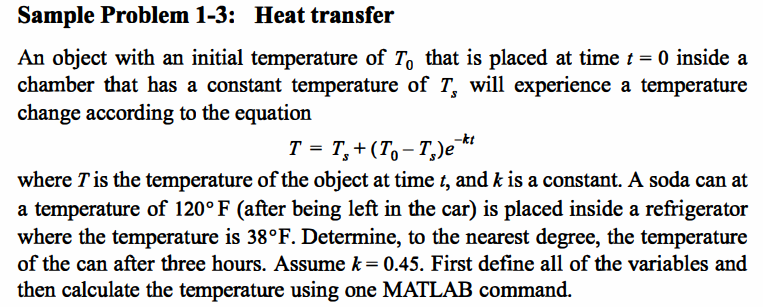

Now, you try:

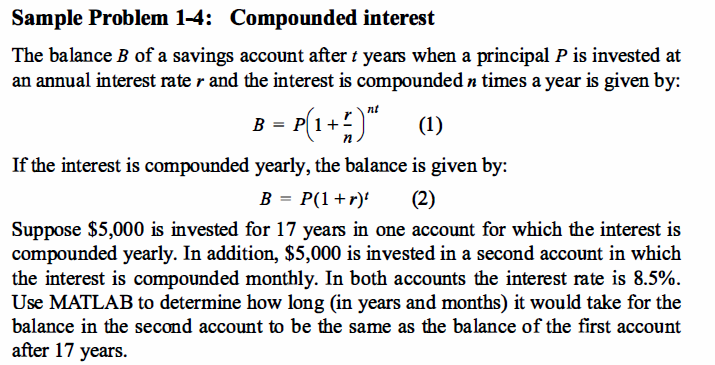

P = 5000

P = 5000

t = 17

t = 17

r= 8.5/100 %0.085

r = 0.0850


B_1 = P*(1+r)^t

B_1 = 2.0011e+04

format bank
disp(B_1)

      20011.31



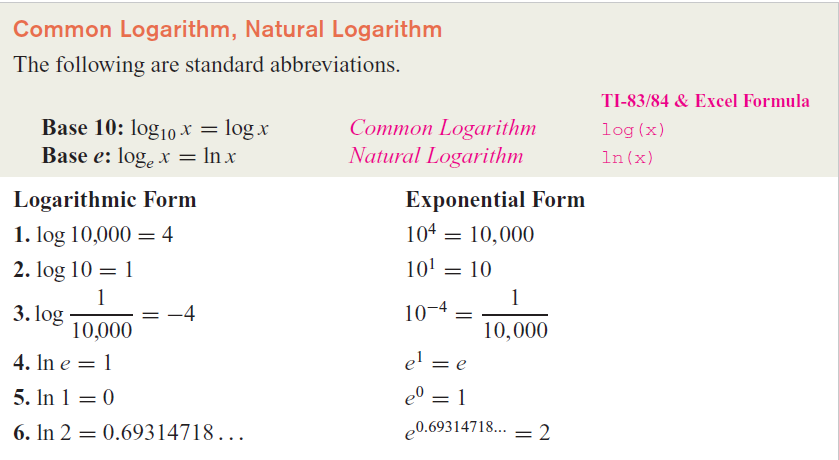

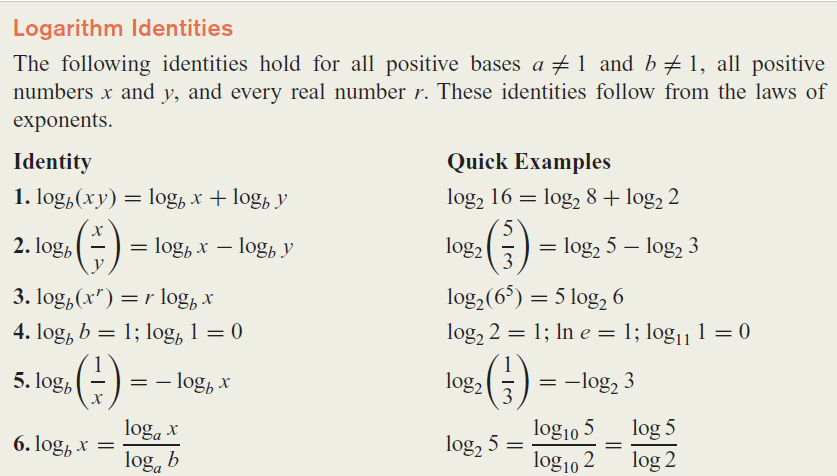


$$B = P*(1+r/n)^{nt}\\

\log(B) = log[P(1+r/n)^{nt}]\\
\log(B) = log(P)+log(1+r/n)^{nt}]\\


\log(B) = log(P)+ntlog(1+r/n)]\\


t = \frac{log(B)-log(P)}{n[log(1+r/n)]} = \frac{log(B/P)}{n[log(1+r/n)]} 
$$


n=12;
t_2 = log(B_1/P)/(n*(log(1+r/n)))

t_2 =          16.37



years = floor(t_2)

years =          16.00


months = ceil((t_2-years)*12)

months =           5.00
